# ColorChecker Spectra of Different Displays

## Iternate displays

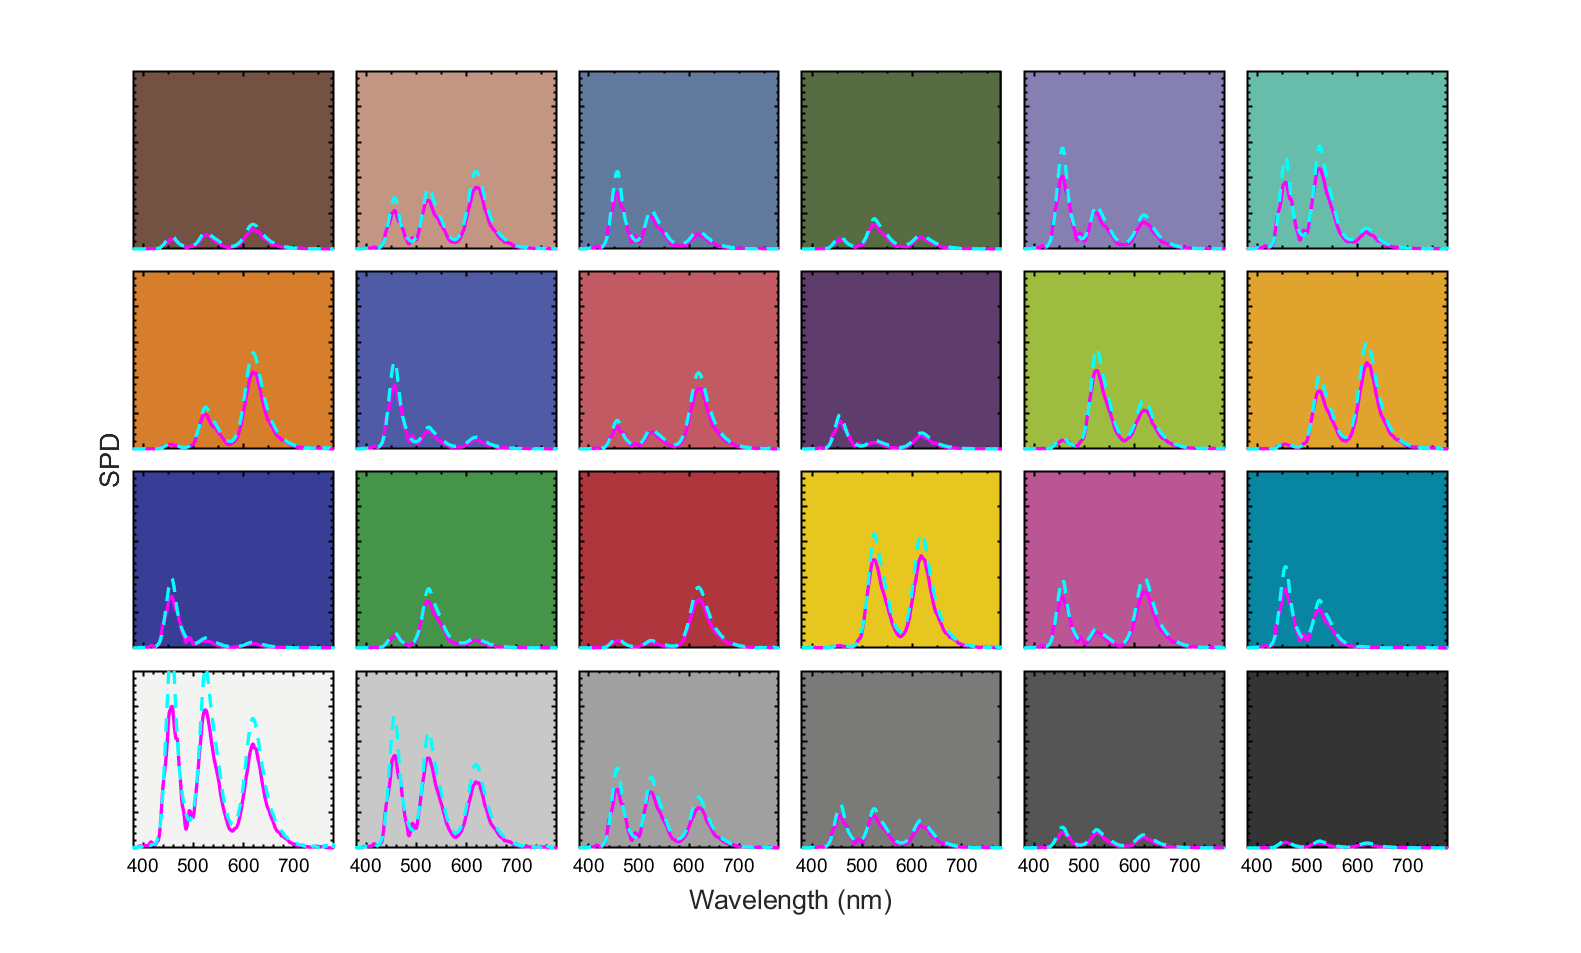

spectra_on_colorchecker('colorchecker_test_result_rift.mat','spectra_on_colorchecker_rift.png')

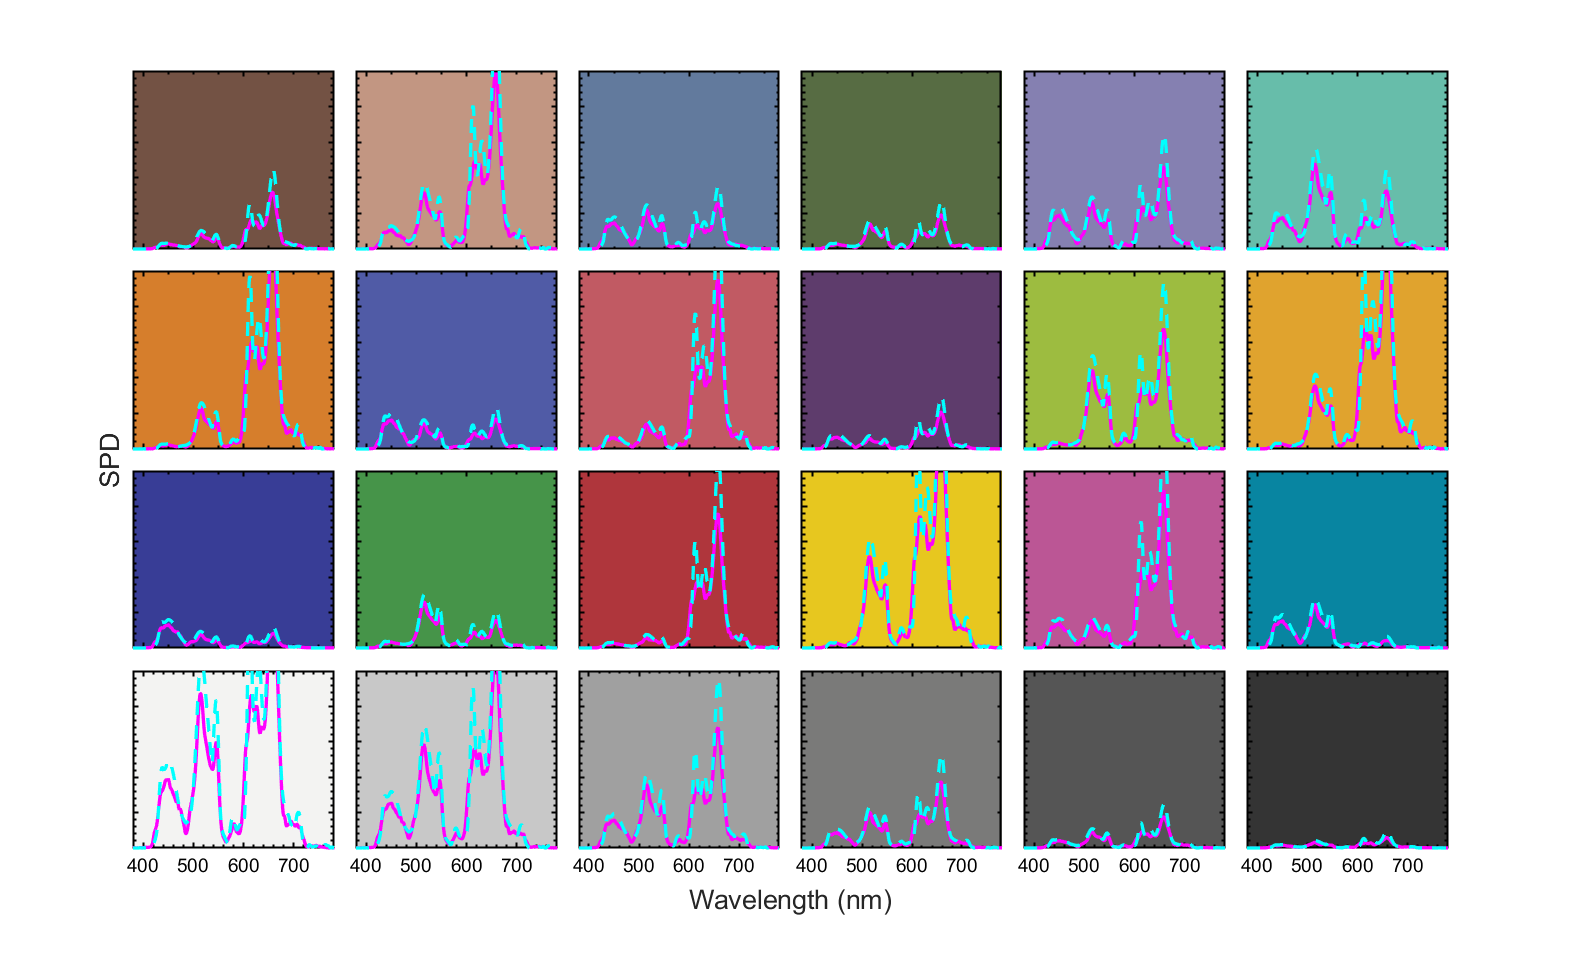

spectra_on_colorchecker('colorchecker_test_result_nec.mat','spectra_on_colorchecker_nec.png')

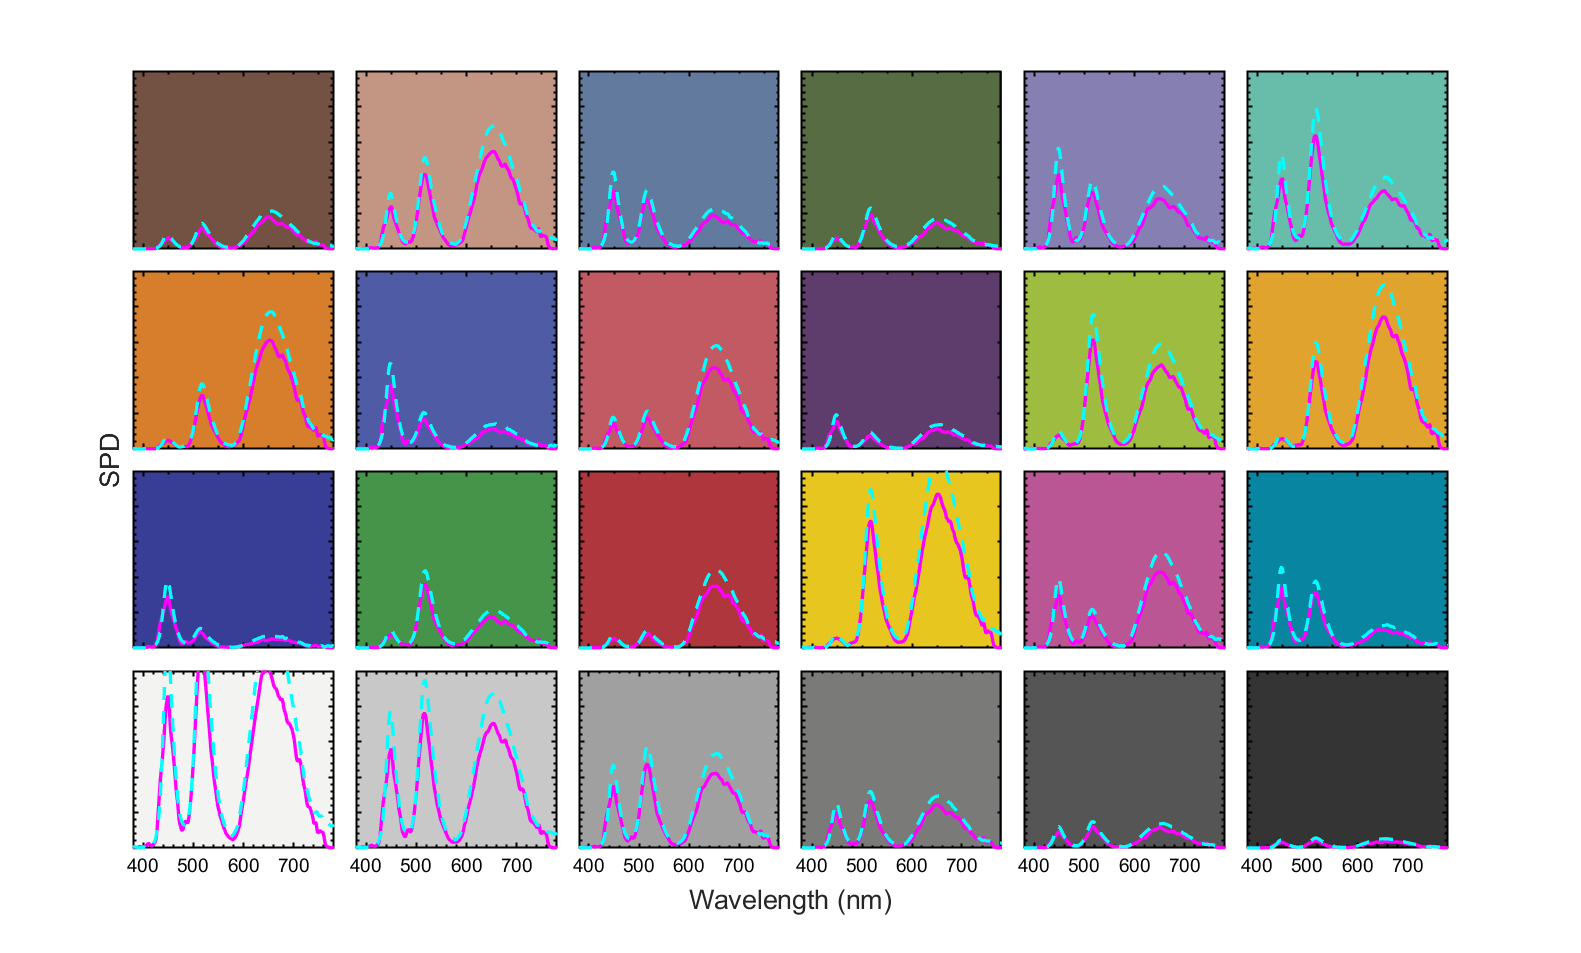

spectra_on_colorchecker('colorchecker_test_result_hp.mat','spectra_on_colorchecker_hp.png')

## The main function here

function spectra_on_colorchecker (fn_in,fn_out)

load(fn_in,'spd_ol490_24','spd_disp_24')

%
% reduce from 401 to 41
%
spec_ol490_24 = zeros(24,41);
for i = 1:24
    s = spd_ol490_24{i};
    s = s(1:10:end);
    spec_ol490_24(i,:) = s;
end

%
% reduce from 401 to 41
%
spec_disp_24 = zeros(24,41);
for i = 1:24
    s = spd_disp_24{i};
    s = s(1:10:end);
    spec_disp_24(i,:) = s;
end

colorchecker = [
    115 82  68;
    194 150 130;
    98  122 157;
    87  108 67;
    133 128 177;
    103 189 170;

    214 126 44;
    80  91  166;
    193 90  99;
    94  60  108;
    157 188 64;
    224 163 46;

    56  61  150;
    70  148 73;
    175 54  60;
    231 199 31;
    187 86  149;
    8   133 161;

    243 243 242;
    200 200 200;
    160 160 160;
    122 122 121;
    85  85  85;
    52  52  52
    ];

### Generate the spectrum plots

clf
td = tiledlayout(4,6,'TileSpacing','compact');
hg = gcf;
set(hg,'Visible','on');

for idx = 1:24

    haxis = nexttile(idx);
    hold on

    plot(380:780,spd_ol490_24{idx},'m-')
    plot(380:780,spd_disp_24{idx},'c--')
    axis([380 780 0 2.5e-4])

    color_rgb = [0 0.5 1];

    %    title(idx)
    yticklabels({});
    PlotBeautify(haxis)
    legend off

    % change the background color
    set(haxis,'Color',colorchecker(idx,:)/255);

    if idx < 19
        xticklabels({});
    end

    haxis.XAxis.FontSize = 14;

    yticklabels({});

    %     if mod(idx,6)==1
    %         ylabel('SPD');
    %     end

end

td.XLabel.String = 'Wavelength (nm)';
td.XLabel.FontSize = 20;

td.YLabel.String = 'SPD';
td.YLabel.FontSize = 20;

hg.Position = [97 134 1581 953];
saveas(hg,fn_out)

end